clc
clear all
close all
addpath("functions")

## **1. GP complexity**

This section of the code is dedicated to answering question 3.1 and all its 5 sub-questions.

%Assigning given values
hyp = [0.05;1]; %defining hyper parameters
Nd = [10] % 15 20];%different Nd values for data generation

Nd = 10

N = Nd.^3;

#### Testing GPregression for differently sized data sets

j_lim = 1;
i_lim = length(Nd);

% Preallocate matrices for the times
elapsed_times = zeros(j_lim, i_lim);
inverse_times = zeros(j_lim, i_lim);
mean_times = zeros(j_lim, i_lim);
covariance_times = zeros(j_lim, i_lim);
pre_allocation_times = zeros(j_lim, i_lim);

for j = 1:j_lim
    for i = 1:i_lim  %Second for loop for each dataset with a different Nd value.
        %generate dataset
        [X, y, Xstar] = getdata(Nd(i), hyp);
        if Nd(i) == 10
            X1 = X;
            y1 = y;
            Xstar1 = Xstar;
        end
    
        %Perform GP regression, time it and calculate the models mean and covariance for
        %new points and kernel matrix for training points.
        function_timer = tic;
        [GPmean, GPcov, k_matrix, inverse_time, mean_time, covariance_time, pre] = GPregression(X, y, Xstar, hyp);
        elapsed_time = toc(function_timer);
    
        %separate line in order to calculate average elapsed time later on
        %in the code
        elapsed_times(j,i) = elapsed_time;
        inverse_times(j,i) = inverse_time;
        mean_times(j,i) = mean_time;
        covariance_times(j,i) = covariance_time;
        pre_allocation_times(j,i) = pre;
    
        %Save relevantdata in results parameter.
        %results.GPmodel = GPmodel;
        %results.predictions = predictions;
        results.mean = GPmean;
        results.cov = GPcov;
        results.k_matrix = k_matrix;
        results.elapsed_time = elapsed_time;
        results.Nd = Nd(i);
    
        %extra output to find the time
        results.inverse_time = inverse_time; 
        results.mean_time =  mean_time; 
        results.covariance_time =  covariance_time;
        results.pre_allocation_time = pre;
    
        %allocate output of the model
        GP_data{j,i} = results;
    end
end

% Calculate the average elapsed time per Nd value
average_elapsed_time = mean(elapsed_times, 1);
average_inverse_time = mean(inverse_times, 1);
average_mean_time = mean(mean_times, 1);
average_covariance_time = mean(covariance_times, 1);
average_pre_allocation_time = mean(pre_allocation_times, 1);

% Display the average elapsed times
for i = 1:i_lim
    fprintf('Average elapsed time for Nd = %d: %.4f seconds\n', Nd(i), average_elapsed_time(i));
    fprintf('Average inverse time for Nd = %d: %.4f seconds\n', Nd(i), average_inverse_time(i));
    fprintf('Average mean time for Nd = %d: %.4f seconds\n', Nd(i), average_mean_time(i));
    fprintf('Average covariance time for Nd = %d: %.4f seconds\n', Nd(i), average_covariance_time(i));
    fprintf('Average pre-allocation time for Nd = %d: %.4f seconds\n', Nd(i), average_pre_allocation_time(i));
end

Average elapsed time for Nd = 10: 0.5700 seconds


Average inverse time for Nd = 10: 0.0869 seconds


Average mean time for Nd = 10: 0.0012 seconds


Average covariance time for Nd = 10: 0.1523 seconds


Average pre-allocation time for Nd = 10: 0.2248 seconds


#### Plotting 3D results for N=1000

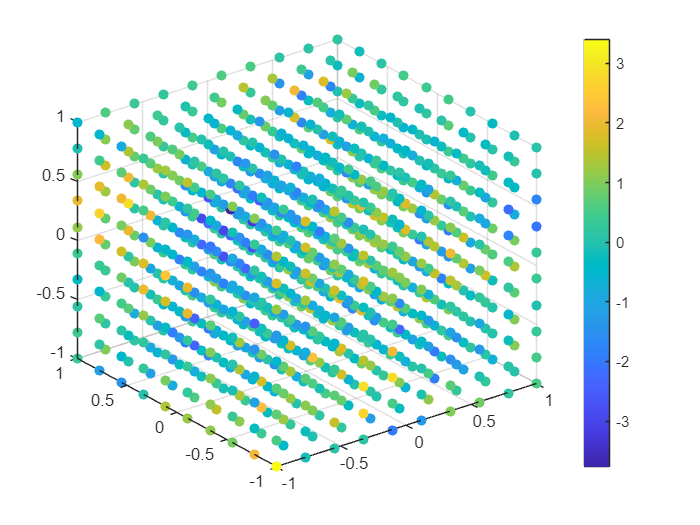

%Getting predictions of model for Nd = 10
%preds = GP_data{1}.predictions;
preds = GP_data{1}.mean;

%3D scatterplot of data + colorbar
scatter3(X1(:,1),X1(:,2),X1(:,3),[],y1,'filled')
colorbar;

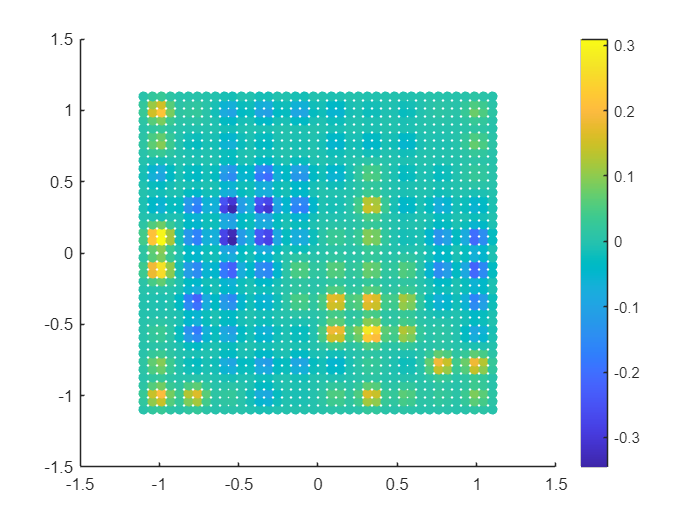


%Scatterplot of predictions
scatter(Xstar1(:,1),Xstar1(:,3),[],preds,'filled')
colorbar;

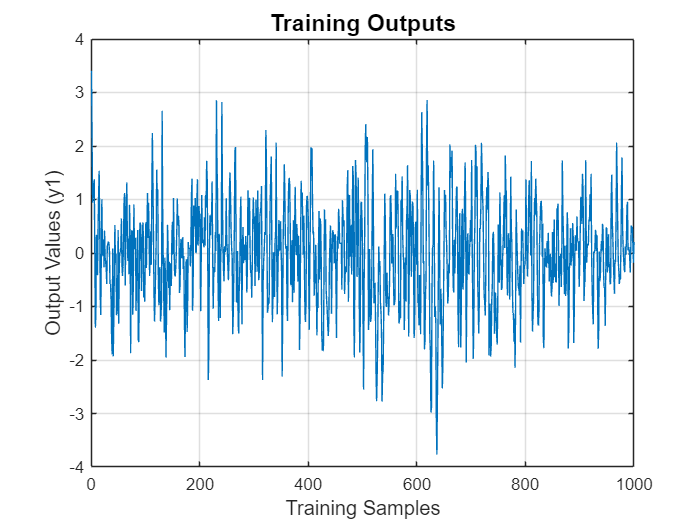


%Additional plots to understand the data and for the report
figure; %Output data plot
plot(y1); 
title('Training Outputs', 'FontSize', 14);
xlabel('Training Samples', 'FontSize', 12);
ylabel('Output Values (y1)', 'FontSize', 12);
grid on;

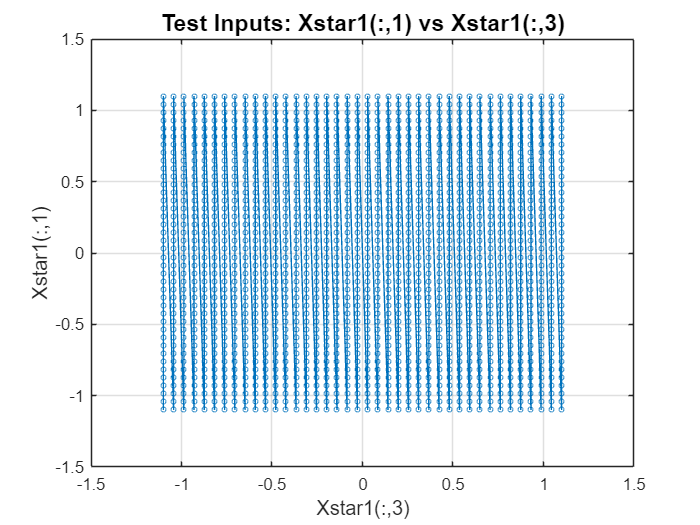


figure; %Test input data plot (Xstar1(:,2) is just zeros so won't be included).
plot(Xstar1(:,3), Xstar1(:,1),'o-', 'MarkerSize', 3);
title('Test Inputs: Xstar1(:,1) vs Xstar1(:,3)', 'FontSize', 14);
xlabel('Xstar1(:,3)', 'FontSize', 12);
ylabel('Xstar1(:,1)', 'FontSize', 12); 
grid on;  

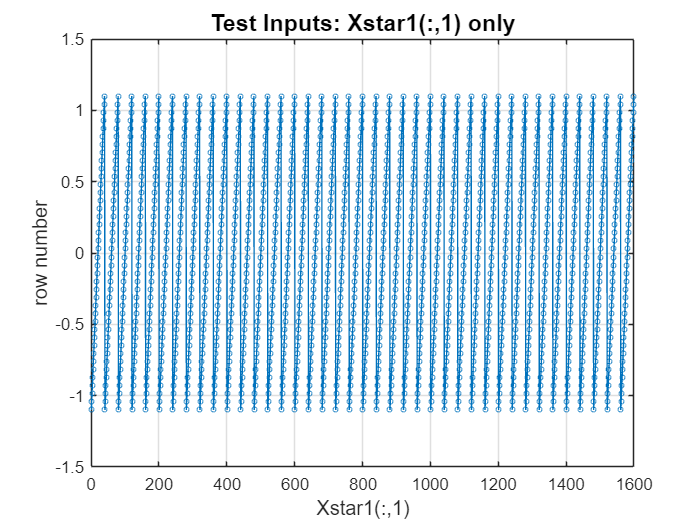


figure; %Test input data plot (Xstar1(:,2) is just zeros so won't be included).
plot(Xstar1(:,1), 'o-',  'MarkerSize', 3);
title('Test Inputs: Xstar1(:,1) only', 'FontSize', 14);
xlabel('Xstar1(:,1)', 'FontSize', 12);
ylabel('row number', 'FontSize', 12); 
grid on;  

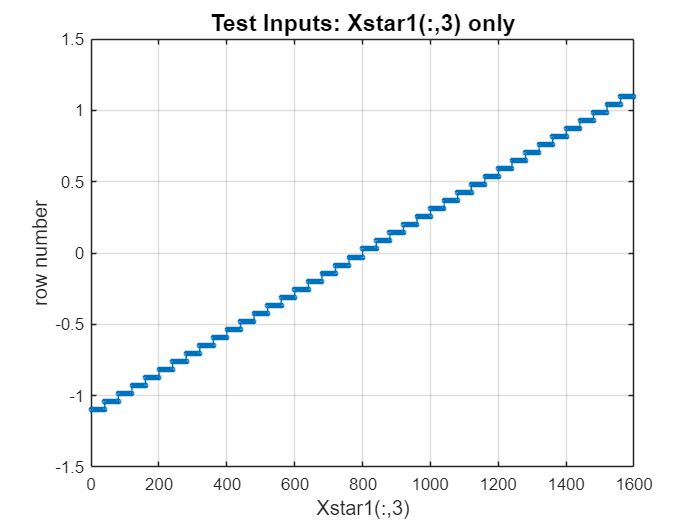


figure; %Test input data plot (Xstar1(:,2) is just zeros so won't be included).
plot(Xstar1(:,3), 'o-', 'MarkerSize', 3);
title('Test Inputs: Xstar1(:,3) only', 'FontSize', 14);
xlabel('Xstar1(:,3)', 'FontSize', 12);
ylabel('row number', 'FontSize', 12); 
grid on;

## 2. Kernel Matrix as Tensor Train

K = GP_data{1}.k_matrix;        %Kernel matrix for 10^3 inputs.
I = [10 10 10]; J = [10 10 10]; %Given size dimensions
eps = 1e-10;                    %Given epsilon value

%reshaping matrix into tensor in order to make it ready for TT_SVD
K_tensor = reshape(K,[I, J]);
K_tensor1 = permute(K_tensor,[1,4,2,5,3,6]);
K_tensor2 = reshape(K_tensor1,I(1)*J(1),I(2)*J(2),I(3)*J(3));

%Turning the tensor into a tensor train.
[tt_K1,rel_err1] = TT_SVD(K_tensor1,eps);
[tt_K2,rel_err2] = TT_SVD(K_tensor2,eps);

%calculating the compression ratio
num_el_tt1 = TT_numel(tt_K1);
num_el_tt2 = TT_numel(tt_K2);

fprintf("the number of elements of the first tensor train is %d and of the 2nd tensor train %d",num_el_tt1,num_el_tt2);

the number of elements of the first tensor train is 600 and of the 2nd tensor train 300


numel_k = numel(K);
comp_ratio1 = num_el_tt1/numel_k

comp_ratio1 = 6.0000e-04

comp_ratio2 = num_el_tt2/numel_k

comp_ratio2 = 3.0000e-04


Ranks_tt_K1 = TT_get_ranks(tt_K1)

Ranks_tt_K1 =      1
    10
     1
    10
     1
    10
     1


Ranks_tt_K2 = TT_get_ranks(tt_K2)

Ranks_tt_K2 =      1
     1
     1
     1


## 3. Kernel Matrix as Kronecker Product

x1 = linspace(-1,1,10)';
x2 = linspace(-1,1,10)';
x3 = linspace(-1,1,10)';

K1 = kernel_matrix_dimension(x1, hyp(1), hyp(2));
K2 = kernel_matrix_dimension(x2, hyp(1), hyp(2));
K3 = kernel_matrix_dimension(x3, hyp(1), hyp(2));

K4 = axis_aligned_kernel2(x1, hyp(1), hyp(2));
K5 = axis_aligned_kernel2(x2, hyp(1), hyp(2));
K6 = axis_aligned_kernel2(x3, hyp(1), hyp(2));

assert(sum(K1-K4,'all') < 1e-9)
assert(sum(K2-K5,'all') < 1e-9)
assert(sum(K3-K6,'all') < 1e-9)

K_kron = kron(K3,K2);
K_kron = kron(K_kron,K1);
assert(sum(k_matrix-K_kron,'all') < 1e-9)

K_test_inv = kron(inv(K3),inv(K2));
K_test_inv = kron(K_test_inv,inv(K1));
assert(sum(K_test_inv-inv(k_matrix) ,'all') < 1e-9)

3.4

tt_test{1} = reshape(K1,1,[],1);
tt_test{2} = reshape(K2,1,[],1);
tt_test{3} = reshape(K3,1,[],1);
tt_test{4} = 0;

K_test = reshape(TT_reconstruct(tt_test),1000,1000);
assert(sum(K_kron-K_test,'all') < 1e-9)